# Proyecto 3: Movimiento Lunar

**Brayan Alberto Chávez Márquez 195581  **

**Mercedes Citlallic Luna Herrera 163348  **

**Luis Alberto Rojas Carvajal 173357**

## Contexto

El estudio del movimiento de la Luna alrededor de la Tierra y del Sol ha sido una parte fundamental de la astronomía desde la antigüedad. En la antigua Grecia, filósofos como Aristóteles y Platón ya se interesaban por el movimiento de los cuerpos celestes, aunque no fue hasta la época de Kepler y Newton que se lograron importantes avances en la comprensión del movimiento de la Luna.

En el siglo XVII, el astrónomo alemán Johannes Kepler desarrolló sus tres leyes del movimiento planetario, que describen la forma en que los planetas se mueven alrededor del Sol en órbitas elípticas. Estas leyes también se aplican al movimiento de la Luna alrededor de la Tierra.

" Mientras tanto, en el siglo XVII, el físico y matemático inglés Isaac Newton formuló su ley de gravitación universal, que establece que cualquier objeto en el universo atrae a cualquier otro objeto con una fuerza proporcional a la masa de cada objeto y inversamente proporcional al cuadrado de la distancia entre ellos" (NASA, 1999). Gracias a Newton y el desarrollo de esta ley permitió a los científicos entender mejor la relación gravitatoria entre la Luna, la Tierra y el Sol, y desarrollar modelos matemáticos precisos del movimiento de la Luna.

## Identificación del problema

Como estudiantes desconocemos cómo es el movimiento de la luna con respecto a la Tierra y Sol, por lo tanto, el propósito del proyecto es simular y representar el movimiento de la Luna en su órbita alrededor del Sol, y cómo las fuerzas gravitatorias de la Tierra y el Sol afectan a este movimiento. Por otra parte, queremos resolver las preguntas de ¿La Luna gira alrededor de la Tierra o del Sol? ¿Cómo es la trayectoria que sigue la Luna durante un año? Estas incognitas se resolverán a partir de un modelado de un sistema dinámico complejo utilizando un sistema de ecuaciones diferenciales. 

## Objetivo

Modelar y simular el movimiento de la Luna alrededor de la Tierra y del Sol. 

## **Requerimientos del problema**

El problema que se presenta se basa en la necesidad de crear un modelo matemático que permita describir y visualizar el movimiento de la Luna alrededor de la Tierra y el Sol en su órbita. Este tipo de problemas son comunes en la física y la astronomía, y requieren el uso de herramientas matemáticas y cálculos complejos.

Para poder modelar el movimiento orbital de la Luna y la Tierra, es necesario utilizar las leyes de la física, en particular, la ley de la gravitación universal de Newton. 

En este caso el objeto más relevante será el Sol ya que su masa es mucho mayor a la de la Tierra y la Luna, de este modo la fuerza que ejerce sobre los cuerpos es mayor y podría ser relevante al momento de determinar la órbita de la Luna. Se debe de tomar en cuenta las distancias que hay entre los cuerpos celestes.

Por otra parte, se necesita impletar un sistema dinámico utilizando un sistema de ecuaciones diferenciales. La razón es que se necesitaba para simular la dinámica del sistema solar. La fuerzas que se producen por los diferentes cuerpos celestes van cambiando, por lo tanto, las fuerzan no son triviales de calcular, entonces es necesario plantear sistema de ecuaciones diferenciales para describir cómo cambian las posiciones y velocidades de los cuerpos celestes un intervalo de tiempo.

El script hará uso de las métodos RK4 (Runge-Kutta de cuarto orden) y ABM4 (Adams-Bashforth-Moulton de cuarto orden) para resolver las ecuaciones diferenciales que describen el movimiento de la Tierra y la Luna en su órbita; así como también, se implementaran metodos predeterminados de matlab, ODE113 o ODE45, para comparar los tiempos de ejecución de cada método. Finalmente, se desarrollará un modelo matemático para resolver el sistema dinámico. 

## **Modelo matemático**

Para la solución del proyecto se utiliza la constante de gravitación por la la masa de un cuerpo celeste. La justificación es que la constante de G*m tiene menor de redondeo que sì utilizaramos la constante de gravitación o la masa del cuerpo celeste; por ejemplo, la masa del sol. Por otra parte, .para resolver la interación  gravitatoria entre dos cuerpos se puede expresar de la siguiente forma:


$$\vec{F} \;=\;\frac{G*\textrm{m1}*\textrm{m2}}{r^2 }\cdot \overset{\longrightarrow }{u}$$
 

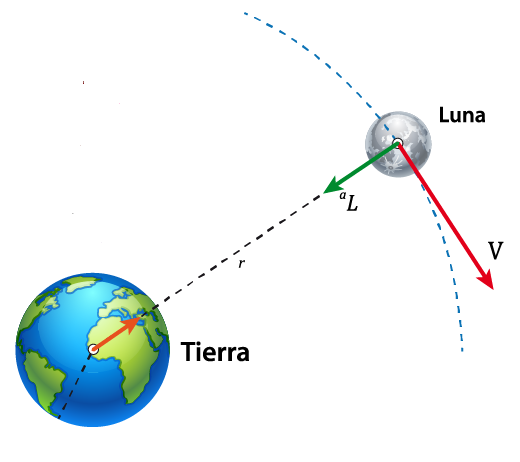

Donde 

- F: es la fuerza de atracción gravitatoria entre dos masas, en Newtons.

- G: es la constante de gravitación universal, en nuestro caso su valor es de 6.673484E-11.

- m1: es la masa de uno de los cuerpos,en kg.

- m2: es la masa de otro de los cuerpos, en kg,

- r: la distancia que los separa, en metros.

- $\overset{\longrightarrow }{u}$es el vector unitario que nos indica la dirección por medio de un vector con componentes (x,y,z)

Segun Leskow (2021) afirma que fuerza es directamente proporcional al producto de las masas de los cuerpos y la constante gravitacional e inversamente proporcional al cuadrado de la distancia que los separa. Las posiciones iniciales como también las velocidades iniciales son tomadas a partir de una fuente de la nasa en un día en específico, por lo tanto, son constantes en nuestro intervalo de tiempo. Nuestro modelo consiste en recibir un vector con la siguiente forma ${\left\lbrack \begin{array}{c}
r_0 \\
v_o 
\end{array}\right\rbrack }^{\prime }$ donde $r_0$ simboliza las posiciones iniciales de nuestro cuerpo celeste calcular y $v_o$ simboliza las velocidades iniciales. Como punto importante tanto la posiciones iniciales como las velocidades iniciales estan expresadas en cordenadas (x,y,z) que nos indican en un espacio de dimensio $\Re^3$. Por otra parte, tenemos una $y^{\prime } =f\left(t,y\right)$ una función de primer orden que depende depende del tiempo y la posición. Gracias a la definición de esta ecuación diferencial, y a la definción del vector con las posiciones iniciales podemos plantear un sistema dinámico de ecuaciones diferenciales. 

Independiente de las funciones que resuelven ecuaciones diferenciales de orden uno o dos tales como RK4 o Ode36, lo que nos enfocamos es definir una función de dos variables que dependen del tiempo y la posición. Por lo tanto, el desarollo de esta función nos permite realizar el siguiente cambio de variable ${\left\lbrack \begin{array}{c}
r_0 \\
v_o 
\end{array}\right\rbrack }^{\prime } \longrightarrow \left\lbrack \begin{array}{c}
v\\
a
\end{array}\right\rbrack$ a partir de las velocidades iniciales se tiene que obtener la aceleración. Para la obtención de la aceleración, utilizamos una matriz de posiciones del cuerpo celeste a resolver en parelo con una matriz de velocidades. La obtención de la fuerza sería de la siguiente forma:


$$\vec{F} \;=\;\frac{G*\textrm{m1}*\textrm{m2}}{r^2 }\cdot \overset{\longrightarrow }{u}$$


Hay que recordar que sí queremos simular el movimiento de la Tierra, la fuerza que recibe la Tierra es la suma de la fuerza del Sol y la Luna. Por lo tanto, de forma generica la suma de la fuerzas de un cuerpo dado n cuerpos de referencias en nuestro sistema se puede expresar como: 


$${\vec{F} }_C \;=\overset{n}{\underset{i\;=\;1}{\Sigma} } \;\frac{G*\textrm{m1}*\textrm{m2}}{r^2 }\cdot \overset{\longrightarrow }{u}$$


Donde 

- $F_c$: es la fuerza de atracción gravitatoria del cuerpo celeste de referencia

- **G**: es la constante de gravitación universal, en nuestro caso su valor es de 6.673484E-11.

- **m1**: es la masa de uno de los cuerpos,en kg.

- **m2**: es la masa de otro de los cuerpos, en kg,

- **r**: la distancia que los separa, en km^3.

- $\overset{\longrightarrow }{u}$es el vector unitario que nos indica la dirección por medio de un vector con componentes (x,y,z)

- n representa el número total de cuerpos celestes. Por ejemplo, para nuestro caso sí queremos representar la fuerza que recibe la Tierra, entonces n = 2, es decir, la suma de la fuerza de la Luna respecto a la Tierra más la fuerza del Sol respecto a la Tierra. 

Al momento de realizar nuestro cambio de variable ${\left\lbrack \begin{array}{c}
r_0 \\
v_o 
\end{array}\right\rbrack }^{\prime } \longrightarrow \left\lbrack \begin{array}{c}
v\\
a
\end{array}\right\rbrack$ como nos importa conocer la aceleración del cuerpo celeste dado las n cuerpos de referencia. Recordando el calculo de la aceleración como $a_c =\frac{\vec{F} }{m_c }$ donde la $a_c \;$es la aceleración del cuerpo, $m_c$ es la masa del cuerpo y $\vec{F}$es la suma de las fuerzas, entonces podemos expresar la acelaración del cuerpo como $\overset{n}{\underset{i\;=\;1}{\Sigma} } \;\frac{G*\textrm{m1}*m_c }{r^2 }\cdot \frac{1}{m_c }\cdot \overset{\longrightarrow }{u}$ quedandonos $a_c =\overset{n}{\underset{i\;=\;1}{\Sigma} } \;\frac{G*\textrm{m1}}{r^2 }\cdot \overset{\longrightarrow }{u}$ cumpliendose la condición de $G\cdot m$ que nos ayuda a disminuir el error de estimacion.

Además, para resolver numéricamente las ecuaciones diferenciales que describen el movimiento de los cuerpos celestes, se utiliza el método de Runge-Kutta de cuarto orden (RK4), que es una técnica iterativa que aproxima la solución en pasos discretos. Los métodos de Runge-Kutta son un conjunto de algoritmos numéricos iterativos que se utilizan para aproximar la solución de ecuaciones diferenciales. Estos métodos son tanto explícitos como implícitos y se aplican en la resolución de problemas de ingeniería, física y matemáticas. La fórmula para el método de Runge-Kutta de cuarto orden está dada por:

La fórmula para el método de Runge-Kutta de cuarto orden está dada por:

Donde:

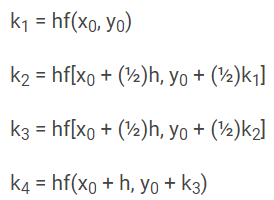

Segun Wikipedia (2019), "el error por paso de cálculo del método de Runge-Kutta de cuarto orden es de $O\left(h^{\left.5\right)} \right)$ y el error acumulado tiene un orden $O\left(h^{\left.4\right)} \right)$".  Por lo tanto, la convergencia del método es del orden $O\left(h^{\left.4\right)} \right)\ldotp$ Se decidió utilizar este método por su alto grado de convergencia.

## **Implementación**

### **Declaración de constantes**

clear;
global spg; 
spg = [1.32712440018E11,3.986004418E5,4.9048695E3];

posInicial_Sol = [-1.354630417531006E+06;1.420546299731827E+04;3.143940434895225E+04];       % Posicion inicial del Sol
posInicial_Tierra =[-2.682456095823074E+07;1.448975704171931E+08;2.413001115289330E+04];    % Posicion inicial de la Tierra
posInicial_Luna = [-2.649907633791349E+07 ;1.451115329759790E+08; 1.920803579456359E+04]; %Posicion inicial de la Luna
posiciones_iniciales = [posInicial_Sol; posInicial_Tierra;posInicial_Luna];

% Velocidades orbitales
velInicial_Sol = [1.636302711538109E-03;-1.558286309774412E-02; 8.961626340290262E-05];
velInicial_Tierra = [-2.981482351984199E+01;-5.295918918751036E+00;-5.493700746179719E-04];
velInicial_Luna = [-3.031955180389345E+01 ;-4.429909321012257E+00 ; 8.719919857097347E-02];
velocidades_iniciales = [velInicial_Sol; velInicial_Tierra;velInicial_Luna];

y0 = [posiciones_iniciales;velocidades_iniciales];
h = 3600;
an = 3600*24*365;

f = @cuerposCelestes; %Creación de la función a resolver

### Prueba con método RK4

tic;
[Tiempo, y] = rk4(f,y0,0,an,h);
tiempoTranscurrido = toc

tiempoTranscurrido = 0.6220

### Prueba con método ABM4

tic;
[Tiempo3, y3] = ABM4(f,y0,0,an,h);
tiempoTranscurrido3 = toc

tiempoTranscurrido3 = 0.2709

### Prueba con método ODE45

tiempoInt = [0:h:an];
tic;
[Tiempo1, y1] = ode45(f,tiempoInt,y0);
tiempoTranscurrido1 = toc

tiempoTranscurrido1 = 0.1461

### Prueba con método ODE113

tic;
[Tiempo2, y2] = ode113(f,tiempoInt,y0);
tiempoTranscurrido2 = toc

tiempoTranscurrido2 = 0.3026

### Gráfica de la simulación de la trayectoria de la Luna y la Tierra con respecto al Sol

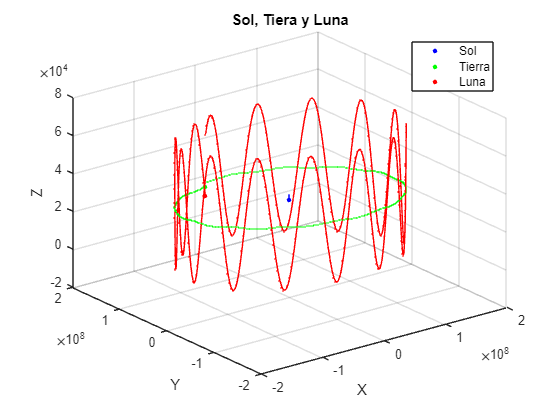

figure();
hold on;
title('');
plot3(y(1,1),y(2,1),y(3,1),'.b','MarkerSize',10);
plot3(y(4,1),y(5,1),y(6,1),'.g','MarkerSize',10);
plot3(y(7,1),y(8,1),y(9,1),'.r','MarkerSize',10);

plot3(y(1,1:24:end),y(2,1:24:end),y(3,1:24:end),'.b','MarkerSize',2);
plot3(y(4,1:24:end),y(5,1:24:end),y(6,1:24:end),'.g','MarkerSize',2);
plot3(y(7,1:24:end),y(8,1:24:end),y(9,1:24:end),'.-r','MarkerSize',2);

xlabel('X');
ylabel('Y');
zlabel('Z');
title('Sol, Tiera y Luna');
legend('Sol','Tierra', 'Luna', 'Location', 'best');
grid on;
view(3)
hold off;

### **Datos para un año de simulación**

h = 100;
tf = 3600*24*365;
f = @cuerposCelestes;
y0 = [posiciones_iniciales;velocidades_iniciales];
[t, y] = rk4(f,y0,0,tf,h);

### Gráfica de la simulación de la trayectoria de la Luna con respecto a la Tierra

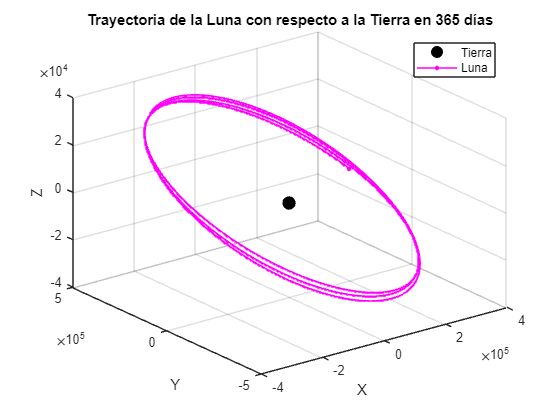

lunaRelativo=[y(7,:)-y(4,:);y(8,:)-y(5,:);y(9,:)-y(6,:)];
%3 meses
tf = 36*24*30*3;
figure();
hold on;
%"Tierra" y(4,0),y(5,0),y(6,0)
plot3(0,0,0,'.k','MarkerSize',30);
plot3(lunaRelativo(1,1),lunaRelativo(2,1),lunaRelativo(3,1),'.-m','MarkerSize',10);
plot3(lunaRelativo(1,1:36:tf),lunaRelativo(2,1:36:tf),lunaRelativo(3,1:36:tf),'.-m','MarkerSize',2);
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Trayectoria de la Luna con respecto a la Tierra en 365 días');
legend('Tierra', 'Luna');
grid on;
view(3)

### **Simulación de órbitas (100 años de la tierra)** 

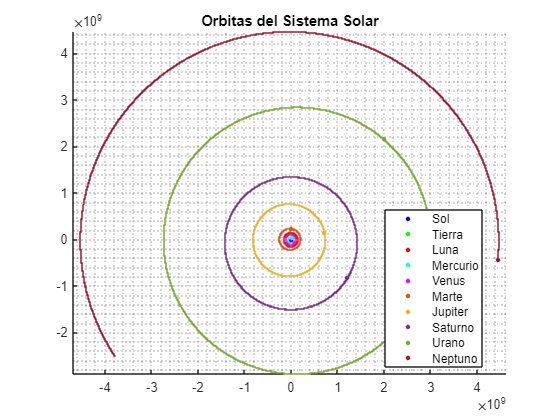

clear
global sgp;
%Orden: Sol,Tierra,Luna,Mercurio,Venus,Marte,Jupiter,Saturno,Urano,Neptuno
sgp = [1.32712440018E11,3.986004418E5,4.9048695E3,2.2032E4,3.24859E5,4.282837E4,1.26686534E8,3.7931187E7,5.793939E6,6.836529E6];
% Posiciones de los cuerpos (Datos del 1ero de enero de 2022)
posInicial_Sol = [-1.354630417531006E6;1.420546299731827E4;3.143940434895225E4];    
posInicial_Tierra =[-2.682456095823074E7;1.448975704171931E8;2.413001115289330E4];    
posInicial_Luna = [-2.649907633791349E7 ;1.451115329759790E8; 1.920803579456359E4];
pMerc=[1.764026173635770E7;4.205586451549117E7;1.724774348507849E6];
pVenus=[8.259475860642716E7;-6.915816357711238E7;-5.762291474659599E6];
pMarte=[7.752583519268439E6 ;2.337987557943932E8;4.707746519684419E6];
pJupiter=[7.224334600170468E8;1.563793813033296E8;-1.681154434344429E7];
pSaturno=[1.217477085834203E9 ;-8.235407623362080E8;-3.415393344975621E7];
pUrano=[1.998730572785467E9;2.158272361448607E9;-1.787799833905435E7];
pNept=[4.450807295340764E9;-4.402241278807998E8;-9.350777495288295E7];
posiciones_iniciales = [posInicial_Sol; posInicial_Tierra;posInicial_Luna;pMerc;pVenus;pMarte;pJupiter;pSaturno;pUrano;pNept];

% Velocidades orbitales
velInicial_Sol = [1.636302711538109E-3;-1.558286309774412E-2; 8.961626340290262E-5];
velInicial_Tierra = [-2.981482351984199E1;-5.295918918751036;-5.493700746179719E-4];
velInicial_Luna = [-3.031955180389345E1 ;-4.429909321012257 ; 8.719919857097347E-2];
vMerc=[-5.413121416137490E1;2.193301681426525E1;6.759056609823457];
vVenus=[2.204951699787050E1;2.687806238064900E1;-9.029101526708860E-1];
vMarte=[-2.329168054360782E1;2.985994216998675;6.343688107030675E-1];
vJupiter=[-2.913214178134590;1.338384166879859E1;9.665521426341250E-3];
vSaturno=[4.872766511120636;7.982087638829929;-3.327210645497218E-1];
vUrano=[-5.046219886831179 ;4.309876668844167 ;8.140382179132333E-2];
vNept=[4.993569179629754E-1 ;5.441397105331187;-1.235787302584317E-1];
velocidades_iniciales = [velInicial_Sol; velInicial_Tierra;velInicial_Luna;vMerc;vVenus;vMarte;vJupiter;vSaturno;vUrano;vNept];
y0 = [posiciones_iniciales;velocidades_iniciales];

h = 3600;
tf = h*24*365*100;
f = @cuerposCelestes;
[t, y] = rk4(f,y0,0,tf,h);
figure();
hold on;
nCuerpos = length(sgp);
color = ['blue','green','red',"#00FFFF","#FF00FF","#D95319","#EDB120","#7E2F8E","#77AC30","#A2142F"];
for i = 1:nCuerpos
    ind = (i-1)*3+1;
    plot3(y(ind,1),y(ind+1,1),y(ind+2,1),'.','Color',color(i),'MarkerSize',10);
    plot3(y(ind,1:48:end),y(ind+1,1:48:end),y(ind+2,1:48:end),'.','Color',color(i),'MarkerSize',2);
end
legend('Sol','', 'Tierra','', 'Luna','','Mercurio','','Venus','','Marte','','Jupiter','','Saturno',...
    '','Urano','','Neptuno' ,'Location', 'best'); 
title('Orbitas del Sistema Solar')
grid minor;
axis equal;

### Rendimiento de nuestro método RK4 y ABM4 

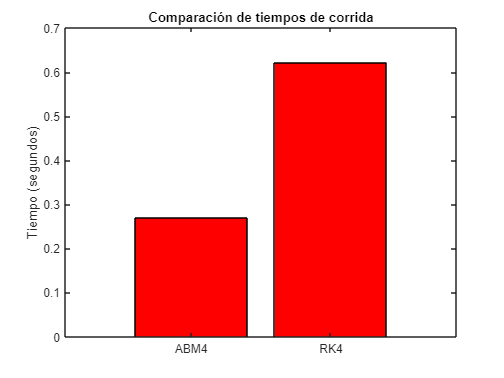

x = categorical({'RK4', 'ABM4'});
bar(x, [tiempoTranscurrido, tiempoTranscurrido3], 'FaceColor', 'red');
ylabel('Tiempo (segundos)');
title('Comparación de tiempos de corrida');

Los métodos propuestos (RK4 y ABM4) muestran una grande diferencia en tiempo de ejecución. En síntesis, el método AMB4 es más eficiente de RK4 debido el método ABM4 utiliza información histórica de los cuatro pasos previos para estimar el siguiente paso, lo que le da una mejor precisión y estabilidad que el método RK4. Además, el método ABM4 puede proporcionar una solución más suave y precisa cuando se enfrenta a problemas de EDO no lineales o problemas que tienen una solución que varía lentamente. De forma experimental, el método RK4 tarda casi el doble del ABM4; lo cual implica que la complejidad del algoritmo ABM4 es mayor que la del RK4. 

### Rendimiento de nuestro método RK4 y ABM4 contra ODE45 y ODE113

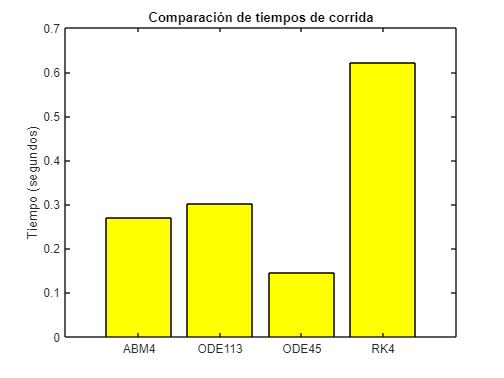

x = categorical({'RK4', 'ODE45', 'ODE113', 'ABM4'});
bar(x, [tiempoTranscurrido, tiempoTranscurrido1, tiempoTranscurrido2, tiempoTranscurrido3], 'FaceColor', 'yellow');
ylabel('Tiempo (segundos)');
title('Comparación de tiempos de corrida');

A pesar de que el método ABM4 resultó más eficiente en tiempos de ejecución en comparación con el método RK4, se probaron otros métodos numéricos para el sistema dinámico en cuestión. La gráfica obtenida muestra que el método ABM4 resulta ser más eficiente que el método ode113, pero menos eficiente que el método ode45. De forma empírica, el algoritmo ABM4 parece estar en un punto intermedio entre los métodos ODE113 y ODE45, ambos métodos numéricos muy potentes. Por otra parte, se observó que el método RK4 presentó un desempeño desfavorable, siendo más lento que los otros tres métodos numéricos mencionados.

## Funciones

## RK4

function [t,y] = rk4(f, y0, t0, tf, h)
    t = t0:h:tf;
    n = length(t);
    y = zeros(length(y0),n);
    y(:,1) = y0;
    h2 = h/2;
    for i = 1:1:n-1
        k1 = f( t(i), y(:,i) );
        k2 = f( (t(i) + (h2)), y(:,i) + (k1*h2) );
        k3 = f( (t(i) + (h2)), y(:,i) + (k2*h2) );
        k4 = f( (t(i) + h), (y(:,i)+(k3*h)) );
        phi = (1/6)*( k1 + (2*k2) + (2*k3) + k4 );
        y(:,i+1) = y(:,i) + (phi*h);
    end
end

## ABM4

function [t,y]=ABM4(f,y0,t0,tf,h)
    t=t0:h:tf;
    n=length(t);
    y=zeros(length(y0) ,n);
    fv=zeros(length(y0),n);
    
    steps=4;
    [t(1:steps),y(:,1:steps)]=rk4(f,y0,t0, t0+h*(steps-1),h);
    fv(:,1:steps)=bsxfun(f,t(1:steps),y(:,1:steps));

    for i=steps:n-1
        %predictor-Adams-Bashford 4
        y(:,i+1)= y(:,i) + (h/24)*( 55*fv(:,i) - 59*fv(:,i-1) + 37*fv(:,i-2) - 9*fv(:,i-3));
        fv(:,i+1)=f(t(i+1),y(:,i+1));
        %corrector Adams-Moulton 4
        y(:,i+1)=y(:,i) + (h/24)*( 9*fv(:,i+1) + 19*fv(:,i) - 5*fv(:,i-1) + fv(:,i-2));
        fv(:,i+1)=f(t(i+1),y(:,i+1));
    end
end    

## CALCULO DE LA ACELERACIÓN

function velocidadAceleracion = cuerposCelestes(~,y) %Tenemos una funcion f(t,y) 
    %El valor de sgp se debe definir antes de llamar a esta función
    global spg
    %sgp = [1.32712440018E11,3.986004418E5,4.9048695E3,2.2032E4,3.24859E5,4.282837E4,1.26686534E8,3.7931187E7,5.793939E6,6.836529E6];
    indVel = length(y)/2;
    nCuerpos = indVel/3;
    velocidadAceleracion = zeros(size(y));
    %Cambio de la posición, i.e. velocidad
    velocidadAceleracion(1:indVel) = y(indVel+1:end);
    %Matriz de posiciones
    %Una columna por cuerpo, posiciones XYZ en los renglones
    pos = reshape(y(1:indVel),[3,nCuerpos]);
    %Primero en la lista - Sol
    sumAc=[0;0;0];
    for j =2:nCuerpos
        dr = pos(:,j)-pos(:,1);
        nr = norm(dr);
        sumAc = sumAc + (sgp(j)/nr^3)*dr;
    end
    velocidadAceleracion(indVel+1:indVel+3)= sumAc;
    %Intermedios - Planetas
    %Sólo aplica si tenemos más de dos cuerpos
    for i = 2:nCuerpos-1
        ind =indVel + (i-1)*3 +1;
        sumAc=[0;0;0];
        for j =1:i-1
            dr = pos(:,j)-pos(:,i);
            nr = norm(dr);
            sumAc = sumAc + (sgp(j)/nr^3)*dr;
        end
        for j =i+1:nCuerpos
            dr = pos(:,j)-pos(:,i);
            nr = norm(dr);
            sumAc = sumAc + (sgp(j)/nr^3)*dr;
        end
        velocidadAceleracion(ind:ind+2)= sumAc;
    end
    %Ultimo en la lista -Luna 
    sumAc=[0;0;0];
    for j =1:nCuerpos-1
        dr = pos(:,j)-pos(:,end);
        nr = norm(dr);
        sumAc = sumAc + (sgp(j)/nr^3)*dr;
    end
    velocidadAceleracion(end-2:end)= sumAc;
end

## Conclusión

El movimiento de la Tierra, la Luna y el Sol puede ser calculado mediante el planteamiento de un sistema dinámico, permitiéndonos conocer las diferentes posiciones a lo largo del tiempo utilizando el parámetro gravitacional estándar, es decir, G*m. Por otra parte, la trayectoria de la Luna es elíptica y varía en distancia durante su recorrido, por lo tanto, podemos a firmar que la Luna gira alrededor de la Tierra. En cuestion de la solución del problema, se utilizaron métodos númericos como rk4 o abm4 que resultan eficientes, sin embargo, al momento de comparar los tiempos de ejecución, el abm4 supero en tiempo de ejecución a otros métodos poderosos tales como ode113 u ode45 que también son eficientes en tiempo de ejecución. En resumen, el estudio del movimiento de la Tierra, la Luna y el Sol es fundamental para comprender la dinámica del sistema solar y las fuerzas que lo rigen. El uso métodos numéricos nos sirven para simular su movimiento nos permite predecir las posiciones y trayectorias con precisión y eficiencia. Esto demuestra la importancia de la física y las matemáticas en la exploración y comprensión del universo que nos rodea.

## Referencias

[1]         JPL Horizons On-Line Ephemeris System. (2023, May 1). Retrieved May 1, 2023, from [https://ssd.jpl.nasa.gov/horizons/app.html#/](https://ssd.jpl.nasa.gov/horizons/app.html#/).

[2]         «La Ley de Gravedad de Newton,» [En línea]. Available: https://imagine.gsfc.nasa.gov/observatories/learning/swift/classroom/docs/law_grav_guide_spanish.pdf.

[3]         «Lunar Constants and Models Document,» 23 Septiembre 2005. [En línea]. Available: file:///C:/Users/merce/Downloads/lunar_cmd_2005_jpl_d32296.pdf.

[4]        «Standard gravitational parameter,»" [En línea].Available: https://en.wikipedia.org/wiki/Standard_gravitational_parameter#.

[5]         «Ley de gravitación universal,» [En línea]. Available: https://es.wikipedia.org/wiki/Ley_de_gravitaci%C3%B3n_universal.

[6]         J. L. Fernández, «Ley de Gravitación Universal,» [En línea]. Available: https://www.fisicalab.com/apartado/ley-gravitacion-universal.

[7]         E. C. Leskow, «Ley de gravitación universal,» 15 Julio 2021. [En línea]. Available: https://concepto.de/ley-de-gravitacion-universal/.

[8]         «Método de Runge-Kutta,» [En línea]. Available: https://es.wikipedia.org/wiki/M%C3%A9todo_de_Runge-Kutta.